# Reduced order model for the soft robot

clearvars;
close all
clc

## Import data

See mat file in [https://drive.google.com/drive/u/0/folders/1z2GUDNL4oAfWPNIhuZ-e4d7AcqhTlSBM](https://drive.google.com/drive/u/0/folders/1z2GUDNL4oAfWPNIhuZ-e4d7AcqhTlSBM) 

load dataDecayObs
rdof = 3;

% load dataDecayObs_john
% yData = yData4;
% V = V4;
% rdof = 4;

nTraj = size(oData,1);
odof = 3;
ndof = size(Xsnapshots,1)/2;

## Plot trajectories in an observable of interest

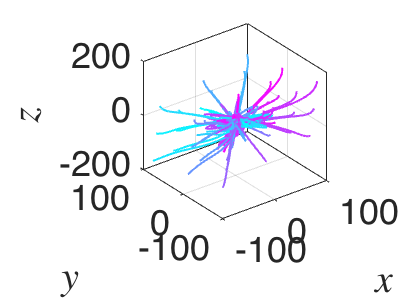

outdofs = [1 2 3];
customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(oData{iTraj,2}(outdofs(1),:),oData{iTraj,2}(outdofs(2),:),oData{iTraj,2}(outdofs(3),:),'Linewidth',1)
end
view(3)
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');

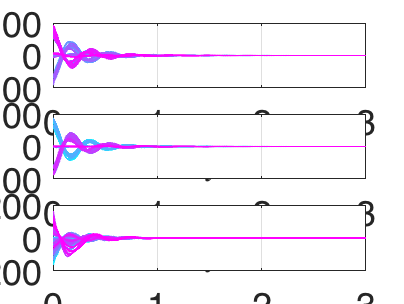


customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
for iTraj = 1:nTraj
    subplot(311);
    plot(oData{iTraj,1},oData{iTraj,2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(oData{iTraj,1},oData{iTraj,2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(oData{iTraj,1},oData{iTraj,2}(outdofs(3),:),'Linewidth',1)
end

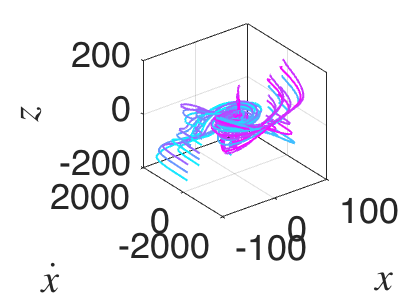


customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(oData{iTraj,2}(outdofs(1),:),oData{iTraj,2}(outdofs(1)+odof,:),oData{iTraj,2}(outdofs(3),:),'Linewidth',1)
end
view(3)
xlabel('$x$','Interpreter','latex');
ylabel('$\dot{x}$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');

## Show PCA infos

Modes were already computed to get yData

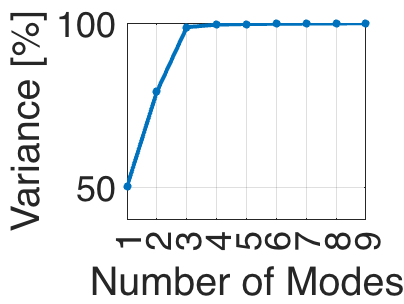

% Perform SVD on displacement field
[~,S,~] = svd(Xsnapshots(1:ndof,:),0);
% Plot variance description: we expect three modes to capture almost all
% variance. Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 9])
set(gca,'XTick',[1:1:9])

## Obtain reduced-order coordinates

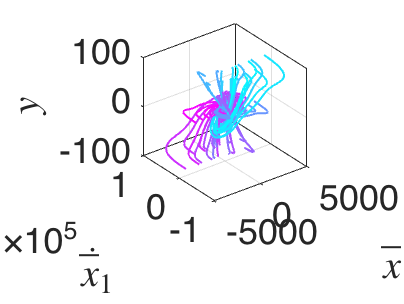

customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(yData{iTraj,2}(1,:),yData{iTraj,2}(1+rdof,:),oData{iTraj,2}(2,:),'Linewidth',1)
end
view(3)
xlabel('$\bar{x}_1$','Interpreter','latex');
ylabel('$\dot{\bar{x}}_1$','Interpreter','latex');
zlabel('$y$','Interpreter','latex');

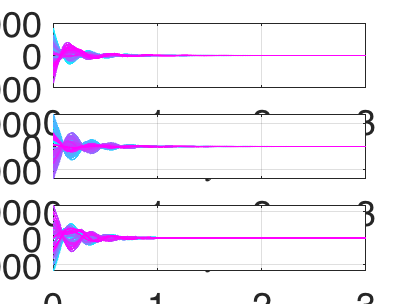


customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_1$','Interpreter','latex');
subplot(312); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');
subplot(313); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_3$','Interpreter','latex');
for iTraj = 1:nTraj
    subplot(311);
    plot(yData{iTraj,1},yData{iTraj,2}(1,:),'Linewidth',1)
    subplot(312);
    plot(yData{iTraj,1},yData{iTraj,2}(2,:),'Linewidth',1)
    subplot(313);
    plot(yData{iTraj,1},yData{iTraj,2}(3,:),'Linewidth',1)
end

## Train and test data

indTest = [1 3 5 7 9 11 13 15];
indTrain = setdiff(1:nTraj,indTest);

## Truncate trajectories

sliceInt = [0.14 2.6];
oDataTrunc = sliceTrajectories(oData, sliceInt);
yDataTrunc = sliceTrajectories(yData, sliceInt);


## Visualize Truncated trajectories

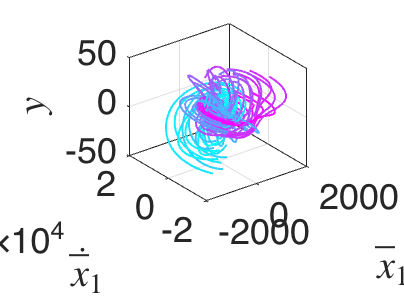

customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(yDataTrunc{iTraj,2}(1,:),yDataTrunc{iTraj,2}(1+rdof,:),oDataTrunc{iTraj,2}(2,:),'Linewidth',1)
end
view(3)
xlabel('$\bar{x}_1$','Interpreter','latex');
ylabel('$\dot{\bar{x}}_1$','Interpreter','latex');
zlabel('$y$','Interpreter','latex');

## Train Geometery of the SSM

SSMDim = 2*rdof;
obsDim = 2*odof;
SSMOrder = 3;
IMInfo = IMGeometry(oDataTrunc(indTrain,:),SSMDim, SSMOrder,'reducedCoordinates',yDataTrunc(indTrain,:));
IMInfoInv = IMGeometry(yDataTrunc(indTrain,:),obsDim, SSMOrder,'reducedCoordinates',oDataTrunc(indTrain,:));

Evaluate parametrization error

% Compute and display error
% Train error
errorGeoTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    oRec = liftTrajectories(IMInfo, yDataTrunc(indTrain(iTraj),:));
    errorGeoTrain(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTrain(iTraj),:))*100;
end
errorGeoTrain

errorGeoTrain =     0.1724    0.2347    0.2464    0.2612    0.1992    0.1530    0.2659    0.2498    0.1744    0.2904    0.1348    0.1771    0.2370    0.2221    0.1954    0.2306    0.1109    0.1999    0.1500    0.1900    0.0962    0.1156    0.1999    0.2354    0.2086    0.2338    0.1403    0.1736    0.1775    0.2786    0.1948    0.2418    0.4244    0.5136    0.3756    0.4997    0.1701    0.2166    0.2025    0.2622    0.2619    0.4220    0.2717    0.7078


meanErrorGeoTrain = mean(errorGeoTrain)

meanErrorGeoTrain = 0.2436

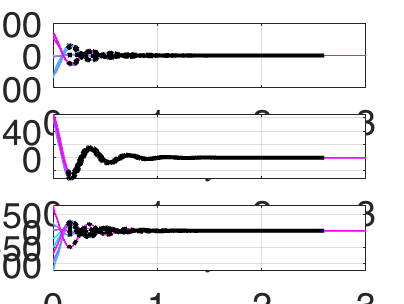

%
errorGeoTest = zeros(1,length(indTest)); 
customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
for iTraj = 1:length(indTest)
    subplot(311);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(3),:),'Linewidth',1)
end
for iTraj = 1:length(indTest)
    oRec = liftTrajectories(IMInfo, yDataTrunc(indTest(iTraj),:));
    errorGeoTest(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTest(iTraj),:))*100;
        subplot(311);
    plot(oRec{1,1},oRec{1,2}(outdofs(1),:),'k:','Linewidth',2)
    subplot(312);
    plot(oRec{1,1},oRec{1,2}(outdofs(2),:),'k:','Linewidth',2)
    subplot(313);
    plot(oRec{1,1},oRec{1,2}(outdofs(3),:),'k:','Linewidth',2)
end

errorGeoTest

errorGeoTest =     0.1313    0.2045    0.2435    0.1947    0.1753    0.1162    0.2288    0.2548


meanErrorGeoTest = mean(errorGeoTest)

meanErrorGeoTest = 0.1936

Evaluate chart error

% Compute and display error
% Train error
errorGeoCTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    yRec = liftTrajectories(IMInfoInv, oDataTrunc(indTrain(iTraj),:));
    errorGeoCTrain(iTraj) = computeTrajectoryErrors(yRec, yDataTrunc(indTrain(iTraj),:))*100;
end
errorGeoCTrain

errorGeoCTrain =     0.1473    0.1958    0.1958    0.1955    0.1878    0.1188    0.2163    0.2214    0.1558    0.2222    0.1024    0.1522    0.1694    0.1627    0.1381    0.1935    0.1095    0.1753    0.1174    0.1485    0.0917    0.1132    0.1490    0.1897    0.1556    0.2226    0.0917    0.1255    0.1372    0.2272    0.1063    0.1245    0.3012    0.4449    0.2883    0.4486    0.1189    0.1676    0.1250    0.1647    0.2420    0.3972    0.2167    0.4970


meanErrorGeoCTrain = mean(errorGeoCTrain)

meanErrorGeoCTrain = 0.1925

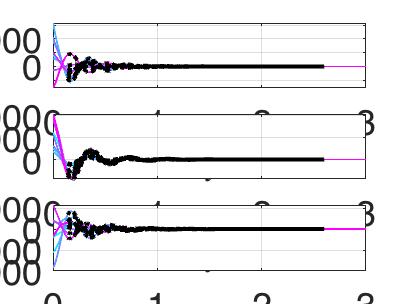

%
errorGeoCTest = zeros(1,length(indTest)); 
customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_1$','Interpreter','latex');
subplot(312); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');
subplot(313); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_3$','Interpreter','latex');
for iTraj = 1:length(indTest)
    subplot(311);
    plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(3),:),'Linewidth',1)
end
for iTraj = 1:length(indTest)
    yRec = liftTrajectories(IMInfoInv, oDataTrunc(indTest(iTraj),:));
    errorGeoCTest(iTraj) = computeTrajectoryErrors(yRec, yDataTrunc(indTest(iTraj),:))*100;
        subplot(311);
    plot(yRec{1,1},yRec{1,2}(outdofs(1),:),'k:','Linewidth',2)
    subplot(312);
    plot(yRec{1,1},yRec{1,2}(outdofs(2),:),'k:','Linewidth',2)
    subplot(313);
    plot(yRec{1,1},yRec{1,2}(outdofs(3),:),'k:','Linewidth',2)
end

errorGeoCTest

errorGeoCTest =     0.1031    0.1550    0.1956    0.1329    0.1644    0.0938    0.1706    0.2135


meanErrorGeoCTest = mean(errorGeoCTest)

meanErrorGeoCTest = 0.1536

Store map in the same variables

sVar = {'map', 'polynomialOrder', 'dimension', 'nonlinearCoefficients', 'phi', 'exponents', 'H'};
for iVar = 1:length(sVar)
    IMInfo.chart.(sVar{iVar}) = IMInfoInv.parametrization.(sVar{iVar});
end

## Train Dynamics of the SSM (mechanical style - continuous dynamical system)

ROMOrder = 3;
RDInfo = IMDynamicsFlow(yDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -3.4956 +16.7981i
  -3.5890 +17.1300i
  -3.6572 +18.3668i




yRec = advectRD(RDInfo, yDataTrunc);

normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = 1.8632

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 0.7931

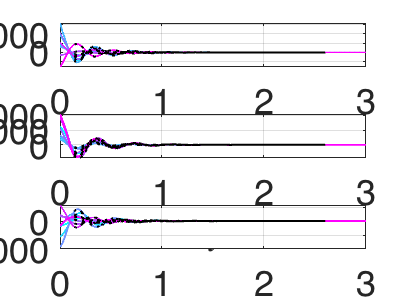


plotAll = 0;
if plotAll == 1
    vPlot = 1:nTraj;
else
    vPlot = indTest;
end
customFigure('subPlot',[3 1]);
xlabel('$t$','Interpreter','latex');
ylabel('$u_1$','Interpreter','latex');
subplot(312); 
xlabel('$t$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');
subplot(313); colororder(cool(length(vPlot)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_3$','Interpreter','latex');
for iTraj = vPlot
    subplot(311);
    plot(yData{iTraj,1},yData{iTraj,2}(1,:),'Linewidth',1)
    subplot(312);
    plot(yData{iTraj,1},yData{iTraj,2}(2,:),'Linewidth',1)
    subplot(313);
    plot(yData{iTraj,1},yData{iTraj,2}(3,:),'Linewidth',1)
end
for iTraj = vPlot
    subplot(311);
    plot(yRec{iTraj,1},yRec{iTraj,2}(1,:),'k:','Linewidth',1)
    subplot(312);
    plot(yRec{iTraj,1},yRec{iTraj,2}(2,:),'k:','Linewidth',1)
    subplot(313);
    plot(yRec{iTraj,1},yRec{iTraj,2}(3,:),'k:','Linewidth',1)
end

## Evaluate global error

% Train error
errorGloTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    oRec = liftTrajectories(IMInfo, yRec(indTrain(iTraj),:));
    errorGloTrain(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTrain(iTraj),:))*100;
end
errorGloTrain

errorGloTrain =     0.7036    0.6659    0.6006    1.2933    1.0619    0.5630    1.3373    0.4321    0.6140    1.6250    0.4133    0.5870    0.8753    0.7896    0.6846    1.3056    0.4069    0.6825    1.0624    1.2251    0.3931    0.4420    0.4542    0.6166    0.4003    0.8026    0.4576    0.5973    0.8445    1.3573    0.4223    0.8030   12.0096    5.8998    6.5708    1.9572    0.7238    0.7723    0.4207    0.7931    4.8530   10.5211    2.1456    4.7926


meanErrorGloTrain = mean(errorGloTrain)

meanErrorGloTrain = 1.7268

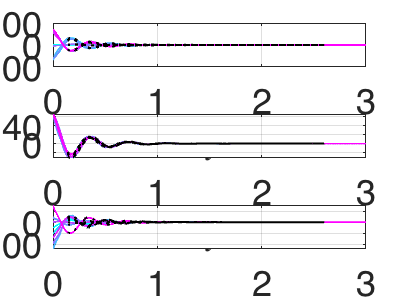

%
errorGeoTest = zeros(1,length(indTest)); 
customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
for iTraj = 1:length(indTest)
    subplot(311);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(3),:),'Linewidth',1)
end
for iTraj = 1:length(indTest)
    oRec = liftTrajectories(IMInfo, yRec(indTest(iTraj),:));
    errorGloTest(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTest(iTraj),:))*100;
        subplot(311);
    plot(oRec{1,1},oRec{1,2}(outdofs(1),:),'k:','Linewidth',1)
    subplot(312);
    plot(oRec{1,1},oRec{1,2}(outdofs(2),:),'k:','Linewidth',1)
    subplot(313);
    plot(oRec{1,1},oRec{1,2}(outdofs(3),:),'k:','Linewidth',1)
end

errorGloTest

errorGloTest =     0.5182    0.9970    1.5150    0.9167    0.9564    0.3168    0.7174    0.7162


meanErrorGloTest = mean(errorGloTest)

meanErrorGloTest = 0.8317

## Understand which mode is more responsbile for what motion

outdofsMat = zeros(3,2*ndof);
output_node = 1354;
outdofsPS =  3*output_node + [1 2 3];

for ii = 1:3
outdofsMat(ii,outdofsPS(ii)) = 1;
end

redDynLinearPart = RDInfo.reducedDynamics.coefficients(:,1:2*rdof);
redStiffnessMat = -redDynLinearPart(rdof+1:end,1:rdof);
[UconsRedDyn,w2] = eig(redStiffnessMat);
[consFreqs,pos] = sort(sqrt(diag(w2))); UconsRedDyn = UconsRedDyn(:,pos);
[consFreqs abs(RDInfo.eigenvaluesLinPartFlow(1:3))];
Ucons = [UconsRedDyn zeros(rdof); zeros(rdof) UconsRedDyn];
Vcons = V*Ucons;
abs(RDInfo.eigenvaluesLinPartFlow(1:3))

ans =    17.1579
   17.5020
   18.7274


modesDir = outdofsMat*Vcons(:,1:rdof)

modesDir =     0.0381    0.0194   -0.0183
    0.0142   -0.0402   -0.0062
    0.0217    0.0049    0.0445


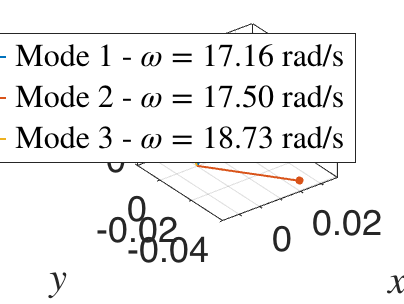

% Plots mode direction
customFigure; classicColors = colororder;
for ii = 1:3
plot3([0 modesDir(1,ii)],[0 modesDir(2,ii)],[0 modesDir(3,ii)],'Linewidth',1,'Color',classicColors(ii,:))
plot3([modesDir(1,ii)],[modesDir(2,ii)],[modesDir(3,ii)],'.','MarkerSize',12,'Color',classicColors(ii,:),'HandleVisibility','off')
end
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
legend(['Mode 1 - $\omega =  ' num2str(round(abs(RDInfo.eigenvaluesLinPartFlow(1)),2)) '$' ' rad/s'],...
    ['Mode 2 - $\omega =  ' num2str(round(abs(RDInfo.eigenvaluesLinPartFlow(2)),2)) '0$' ' rad/s'],...
    ['Mode 3 - $\omega =  ' num2str(round(abs(RDInfo.eigenvaluesLinPartFlow(3)),2)) '$' ' rad/s'],'interpreter','latex')
view(3)
axis equal

% Hence mode 1 is mainly along x, mode 2 along y and mode 3 along z.

## Control


$$H_{\textrm{red}} ={\mathrm{V}}^{\top } M^{-1} H$$


Hred = transpose(V(1:ndof,1:rdof))*(M\H);

normsModalForcing = mean((transpose(V(1:ndof,1:rdof))*(M\H)).^2,1)

normsModalForcing = 	1.0e+03 *

    3.6165    3.6851    2.7069    3.6295


normsNonModalForcing = mean(((eye(ndof)-V(1:ndof,1:rdof)*transpose(V(1:ndof,1:rdof)))*(M\H)).^2,1)

normsNonModalForcing = 	1.0e+03 *

    1.8746    1.5411    1.3337    1.2016


## Setup model for control

Accordin to the slides of June 2

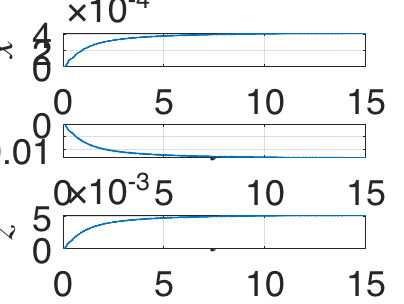

Rauton = RDInfo.reducedDynamics.map;
R = @(t,p,u) Rauton(p) + [zeros(rdof,size(Hred,2)); Hred]*u;
C = IMInfo.parametrization.map;
W = IMInfo.chart.map;

% Example
uFun = @(t) [atan(t)/pi*2; 0; 0; 0];
tTraj = linspace(0,15,1000);
[~,yTraj] = ode45(@(t,p) R(t,p,uFun(t)),tTraj,zeros(2*rdof,1));
yTraj = transpose(yTraj);
oTraj = C(yTraj);
customFigure('subPlot',[3 1]); 
subplot(311); 
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); 
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313);
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
subplot(311);
plot(tTraj,oTraj(outdofs(1),:),'Linewidth',1)
xlim([tTraj(1) tTraj(end)])
subplot(312);
plot(tTraj,oTraj(outdofs(2),:),'Linewidth',1)
xlim([tTraj(1) tTraj(end)])
subplot(313);
plot(tTraj,oTraj(outdofs(3),:),'Linewidth',1)
xlim([tTraj(1) tTraj(end)])

## Integrate the model with inputs

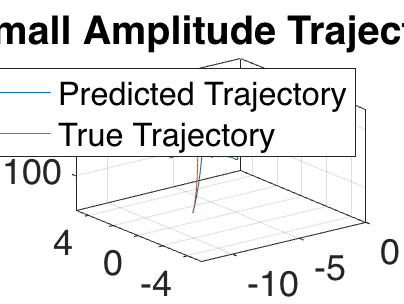

% Load the controls and actual trajectories for figure eight
uFigureEight = readmatrix("../system_data/u_small.csv");
z = readmatrix("../system_data/z_small.csv").';
z_eq = readmatrix("../system_data/z_equilibrium.csv").';
z_eq = [z_eq, 0, 0, 0];

% Original spacing of inputs
T = 10.01;
dt = 0.01;
N = T / dt;
t_span = linspace(0, T, N+1);
z_true = z(4:end, :);


uFun = @(t) transpose(interp1(t_span, uFigureEight, t));
[~,yTraj] = ode45(@(t,p) R(t,p,uFun(t)),t_span,zeros(2*rdof,1));
yTraj = transpose(yTraj);
oTraj = C(yTraj) + z_eq.';

% Visualize the trajectory
customFigure; 
plot3(oTraj(1, :), oTraj(2, :), oTraj(3, :)); 
plot3(z_true(1, :), z_true(2, :), z_true(3, :)); 
legend('Predicted Trajectory', 'True Trajectory')
title('Small Amplitude Trajectory')
view(3)

## Define big amplitude trajectory

% Load the controls and actual trajectories for figure eight
uFigureEight = readmatrix("../system_data/u_big.csv");
z = readmatrix("../system_data/z_big.csv").';
z_eq = readmatrix("../system_data/z_equilibrium.csv").';
z_eq = [z_eq, 0, 0, 0];

% Original spacing of inputs
T = 10.01;
dt = 0.01;
N = T / dt;
t_span = linspace(0, T, N+1);

## Learn control matrix

% Currently using big figure 8 trajectory
z_eight_true = [z(4:end, :); z(1:3, :)];
z_eight_shift = z_eight_true - z_eq.';
U_eight = uFigureEight.';
% Comment this out
% U = U_eight(:, 4:end-3);
% z_shift = z_eight_shift;

% Importing from training data
load diamond_train_full
y = y'; U = u';
z_true = [y(4:end, :); y(1:3, :)];
z_shift = z_true - z_eq.';
t_span = [t, t_span(2:end)+t(end)];
U = [U U_eight(:, 2:end)];
U = U(:, 4:end-3);
z_shift = [z_shift z_eight_shift(:, 2:end)];

Xbar = IMInfo.chart.map(z_shift);
[dXbarDt,Xbar,t] = finiteTimeDifference(Xbar, t_span, 3); % Truncates X_bar 3 places on each side

dXbarDt_ROM = Rauton(Xbar); % Evaluate derivative of ROM dynamics for each Xbar

% Set options for ridgeRegression
varargin = {'R_PolyOrd', [3], 'style', 'default'};
nargin = 5;

L2 = 1 + 0 * exp(0*t);
% [B_learn,l_opt,Err] = ridgeRegression(U, dXbarDt(4:end, :) - dXbarDt_ROM(4:end, :), L2, [], 0);
% B_learn = [zeros(rdof,size(B_learn,2)); B_learn]*u;

% Learn whole B matrix
[B_learn,l_opt,Err] = ridgeRegression(U, dXbarDt - dXbarDt_ROM, L2, [], 0);
R = @(t,p,u) Rauton(p) + B_learn*u;


## Integrate model with inputs (Big amplitude)

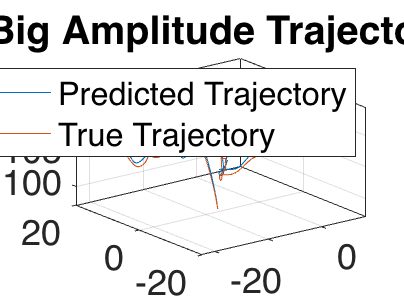

z_true = z(4:end, :);
t_span = linspace(0, T, N+1);
uFun = @(t) transpose(interp1(t_span, uFigureEight, t));
[~,yTraj] = ode45(@(t,p) R(t,p,uFun(t)),t_span,zeros(2*rdof,1));
yTraj = transpose(yTraj);
oTraj = C(yTraj) + z_eq.';

% Visualize the trajectory
customFigure; 
plot3(oTraj(1, :), oTraj(2, :), oTraj(3, :)); 
plot3(z_true(1, :), z_true(2, :), z_true(3, :)); 
legend('Predicted Trajectory', 'True Trajectory')
title('Big Amplitude Trajectory')
view(3)


RMSE = sum(sqrt(mean((oTraj(1:3, :) - z_true).^2))) / size(oTraj, 2)

RMSE = 0.6153

## Reduced dynamics infos

The reduced dynamics is a map of type:

RDInfo.reducedDynamics.map

ans = function_handle with value:
    @(x)W_r*phi(x)

where the coefficients $W_r$ are

RDInfo.reducedDynamics.coefficients

ans =    -0.1591   -0.0068   -0.0110    0.9963   -0.0001   -0.0000    0.0000    0.0000    0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0064   -0.1511   -0.0036   -0.0000    0.9962   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   

and the function $\phi$ collects all the monomials for the states up to the fitting order

RDInfo.reducedDynamics.phi

ans = function_handle with value:
    @(in1)[in1(1,:);in1(2,:);in1(3,:);in1(4,:);in1(5,:);in1(6,:);in1(1,:).^2;in1(1,:).*in1(2,:);in1(1,:).*in1(3,:);in1(1,:).*in1(4,:);in1(1,:).*in1(5,:);in1(1,:).*in1(6,:);in1(2,:).^2;in1(2,:).*in1(3,:);in1(2,:).*in1(4,:);in1(2,:).*in1(5,:);in1(2,:).*in1(6,:);in1(3,:).^2;in1(3,:).*in1(4,:);in1(3,:).*in1(5,:);in1(3,:).*in1(6,:);in1(4,:).^2;in1(4,:).*in1(5,:);in1(4,:).*in1(6,:);in1(5,:).^2;in1(5,:).*in1(6,:);in1(6,:).^2;in1(1,:).^3;in1(1,:).^2.*in1(2,:);in1(1,:).^2.*in1(3,:);in1(1,:).^2.*in1(4,:);in1(1,:).^2.*in1(5,:);in1(1,:).^2.*in1(6,:);in1(1,:).*in1(2,:).^2;in1(1,:).*in1(2,:).*in1(3,:);in1(1,:).*in1(2,:).*in1(4,:);in1(1,:).*in1(2,:).*in1(5,:);in1(1,:).*in1(2,:).*in1(6,:);in1(1,:).*in1(3,:).^2;in1(1,:).*in1(3,:).*in1(4,:);in1(1,:).*in1(3,:).*in1(5,:);in1(1,:).*in1(3,:).*in1(6,:);in1(1,:).*in1(4,:).^2;in1(1,:).*in1(4,:).*in1(5,:);in1(1,:).*in1(4,:).*in1(6,:);in1(1,:).*in1(5,:).^2;in1(1,:).*in1(5,:).*in1(6,:);in1(1,:).*in1(6,:).^2;in1(2,:).^3;in1(2,:).^

the exponents of these monomials are stored in the matrix

RDInfo.reducedDynamics.exponents

ans =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     2     0     0     0     0     0
     1     1     0     0     0     0
     1     0     1     0     0     0
     1     0     0     1     0     0


## Train Discrete-time model

Ts = 0.01;

% Process the data
sim_data = {};
sim_data.oData = oData; sim_data.yData = yData;

resampled_data = data.resample(sim_data, Ts);
oData_d = resampled_data.oData;
yData_d = resampled_data.yData;

% Crop transients
sliceInt = [0.14 2.6];
oDataTrunc_d = sliceTrajectories(oData_d, sliceInt);
yDataTrunc_d = sliceTrajectories(yData_d, sliceInt);

% Train Geometry of SSM
IMInfo_d = IMGeometry(oDataTrunc_d(indTrain,:),SSMDim, SSMOrder,'reducedCoordinates',yDataTrunc_d(indTrain,:));
IMInfoInv_d = IMGeometry(yDataTrunc_d(indTrain,:),obsDim, SSMOrder,'reducedCoordinates',oDataTrunc_d(indTrain,:));

sVar = {'map', 'polynomialOrder', 'dimension', 'nonlinearCoefficients', 'phi', 'exponents', 'H'};
for iVar = 1:length(sVar)
    IMInfo_d.chart.(sVar{iVar}) = IMInfoInv_d.parametrization.(sVar{iVar});
end

RDInfo_d = IMDynamicsMap(yDataTrunc_d(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo_d.eigenvaluesLinPartFlow(1:3)

ans =   -3.4951 +16.8006i
  -3.5827 +17.1471i
  -3.5967 +18.3557i



% Construct discrete-time model
Rauton_d = RDInfo_d.reducedDynamics.map;
R_d = @(k,p,u) Rauton_d(p) + Ts * [zeros(rdof,size(Hred,2)); Hred]*u;
C_d = IMInfo_d.parametrization.map;
W_d = IMInfo_d.chart.map;

## Validate Discrete model with inputs

% Load the controls and actual trajectories for figure eight
uFigureEight = readmatrix("../system_data/u_big.csv");
z = readmatrix("../system_data/z_big.csv").';
z_eq = readmatrix("../system_data/z_equilibrium.csv").';
z_eq = [z_eq, 0, 0, 0];

% Original spacing of inputs
T = 10.01;
dt = 0.01;
N = T / dt;
DeltaT = yData_d{1,1}(2)-yData_d{1,1}(1);
t_span = linspace(0, T, N+1);
t_interp = linspace(1,T,T/DeltaT);
z_ref = repmat(z_eq.', 1, length(t_interp)+1)

z_ref =    -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769
    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132 

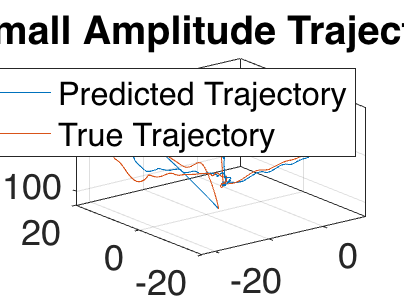

z_true = z(4:end, :);

u_interp = interp1(t_span, uFigureEight, t_interp);

uFun = @(k) u_interp(k,:).';
iters = 0:length(t_interp);
yTraj = iterateMapU(@(k,p) R_d(k,p,uFun(k)),length(iters),zeros(2*rdof,1));
oTraj = C_d(yTraj) + z_ref;

% Visualize the trajectory
customFigure; 
plot3(oTraj(1, :), oTraj(2, :), oTraj(3, :)); 
plot3(z_true(1, :), z_true(2, :), z_true(3, :)); 
legend('Predicted Trajectory', 'True Trajectory')
title('Small Amplitude Trajectory')
view(3)

## Export mapping coefficients and input matrix

% Continuous-time model

% TODO: Save either known input matrix or learned input matrix
% B_r = [zeros(rdof,size(Hred,2)); Hred];
B_r = B_learn;
w_coeff = IMInfo.parametrization.H; % reduced to observed
v_coeff = IMInfo.chart.H; % observed to reduced
r_coeff = RDInfo.reducedDynamics.coefficients;

% Discrete-time model
wd_coeff = IMInfo_d.parametrization.H;
vd_coeff = IMInfo_d.chart.H;
rd_coeff = RDInfo_d.reducedDynamics.coefficients;
Bd_r = Ts * [zeros(rdof,size(Hred,2)); Hred];

py_data = struct();
ssm_model = struct();

ssm_model.w_coeff = w_coeff;
ssm_model.v_coeff = v_coeff;
ssm_model.r_coeff = r_coeff;
ssm_model.B = B_r;

ssm_model.Ts = Ts;
ssm_model.wd_coeff = wd_coeff;
ssm_model.vd_coeff = vd_coeff;
ssm_model.rd_coeff = rd_coeff;
ssm_model.Bd = Bd_r;
py_data.model = ssm_model;

params = struct();
params.SSM_order = SSMOrder;
params.ROM_order = ROMOrder;
params.state_dim = 2*rdof;
params.input_dim = size(H, 2);
params.output_dim = 2*odof;
py_data.params = params;

save('SSM_model.mat', 'py_data', '-v7')
